# **Mid speed scada with DFE equalizer**

**By Miz.Wong, 2018**

**Miz.Wang@Hytera.com**

**Hytera Co,. Ltd.**

## ***System Info***

`--------------------------------------------------------------------------------------`

`Symbol Rate                                                                  10ksym/s`

`Band width                                                                    12.5kHz`

`Modulation type                                                                16-QAM`

`Real information rate                                                        35kBit/s`

`Baseband oversampling rate                                                          8`

`IF oversampling rate                                                               36`

`RF frequency( Only used for calculating VCO error and fd )                     350MHz`

`TX VCO frequency error                                                    1ppm(3.5Hz)`

`TX NCO initial phase                                                               0°`

`Channel info -- SNR                                                               0dB`

`             -- Doppler                                                           2Hz`

`             -- Path gains                                              [0dB -22.3dB]`

`             -- Path delays                                                [0s 5e-6s]`

`RX NCO initial phase                                                              60°`

`DFE taps                                                         1 Forward 1 Backward`

`DFE forgetting factory  `                             `                             0.9`

`Frame structure                                       |Training sequence|Information|`

`-------------------------------------------------------------------------------------`

**1.Clean up workspace**

clear all;
close all;
clc;

**2.Set system parameters**

M        =   16;
Rs       =   10e3;
Rb       =   Rs * log2(M);
BB_OSR   =   8;
FsBB     =   Rs * BB_OSR;
IF_OSR   =   36;
FsIF     =   FsBB * IF_OSR;

Coefs    =   load('FilterCoefs.mat');

coefRRC  =   Coefs.coefRRC;
coefIF   =   Coefs.coefIF;

hMod     =   comm.RectangularQAMModulator( M, 'BitInput', true );
hDem     =   comm.RectangularQAMDemodulator( M, 'BitOutput', true );

T        =   0.04;

nTSHead  =   50;

tBB      =   0 : 1/FsBB : T - 1/FsBB;
tIF      =   0 : 1/FsIF : T - 1/FsIF;

txcVCO   =   350e6;
txcPPM   =   1;
txcFreq  =   100e3;
txcFreq  =   txcFreq + (txcVCO / 1e6)*txcPPM;
txcPhi0  =   0;

rxcFreq  =   100e3;
rxcPhi0  =   pi/3;

fd       =   2;
pdb      =   [0 -22.3];
tau      =   [0 5e-6];
RlChan   =   rayleighchan( (1 / FsIF), fd, tau, pdb);

hEVM     =   comm.EVM( 'ReferenceSignalSource', 'Estimated from reference constellation', ...
                       'ReferenceConstellation', constellation(hMod).' );

hMyDFE   =   fnDFECreate(1, 1, 0.9, hMod, hDem);
hPLLDFE  =   fnDFECreate(1, 1, 0.9, hMod, hDem);

**3.Transmitter**

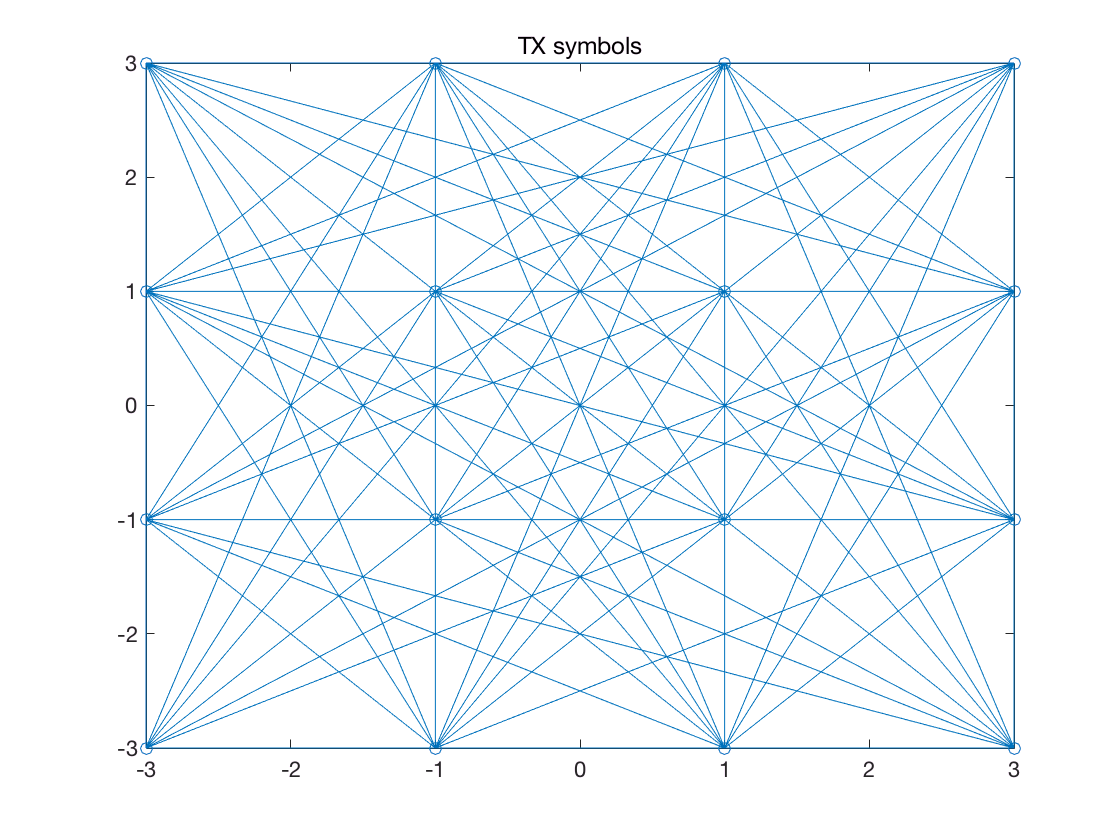

txBit    =   randi( [0,1], T*Rb, 1 );
txSym    =   step(hMod, txBit );
txSymUp  =   zeros( length(txSym)*BB_OSR, 1 );
txSymUp(1 : BB_OSR : end) = txSym;
txSymUp  =   txSymUp * BB_OSR;

txSymUp  =   [zeros(200,1); txSymUp; zeros(200,1);];

txSymUp  =   FilterConv( txSymUp.', coefRRC' ).' ;

txSymIF  =   zeros( length(txSymUp)*IF_OSR, 1 );
txSymIF(1 : IF_OSR : end) = txSymUp;
txSymIF  =   txSymIF * IF_OSR;
txSymIF  =   FilterConv( txSymIF.', coefIF' ).' ;
tIF      =   0 : 1/FsIF : length(txSymUp)/FsBB - 1/FsIF;
txSymIF  =   txSymIF .* exp( 1j*( 2*pi*txcFreq*tIF' + txcPhi0 ) );

figure;  plot(txSym, 'o-');  title('TX symbols');

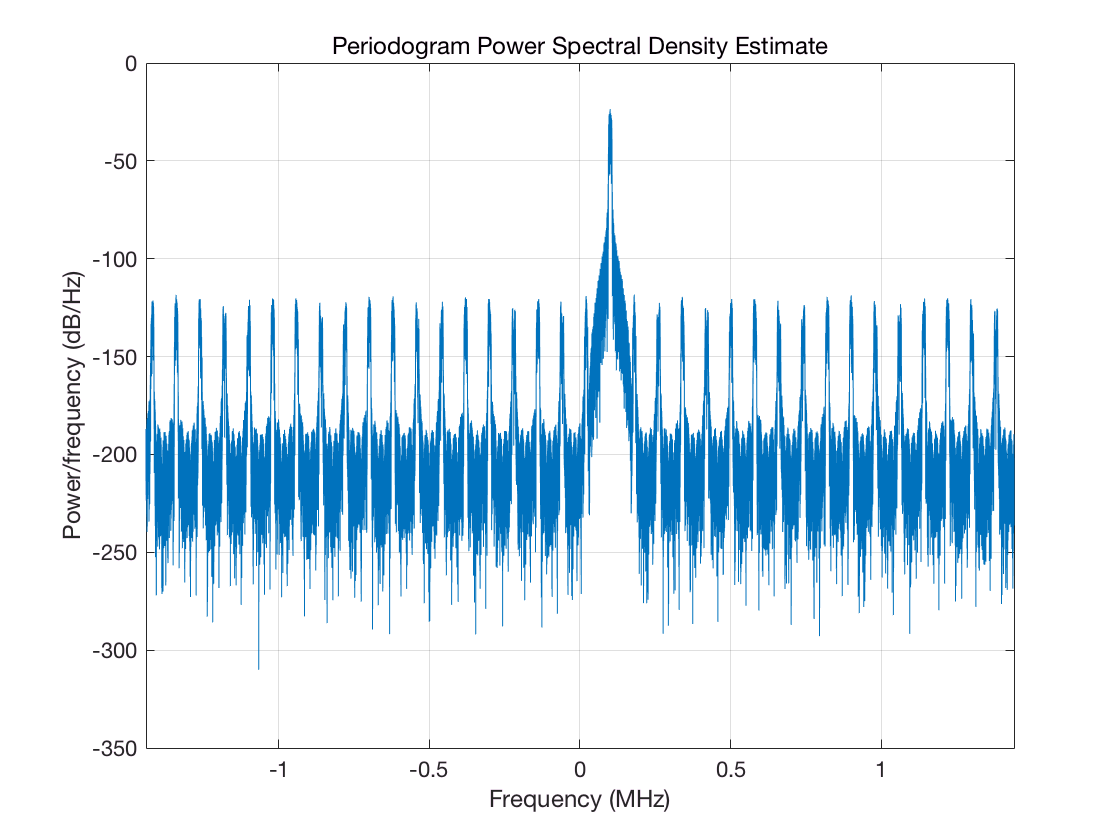

hs       =   spectrum.periodogram; figure;psd(hs, txSymIF, 'Fs',FsIF, 'CenterDC',true);

**4.Channel**

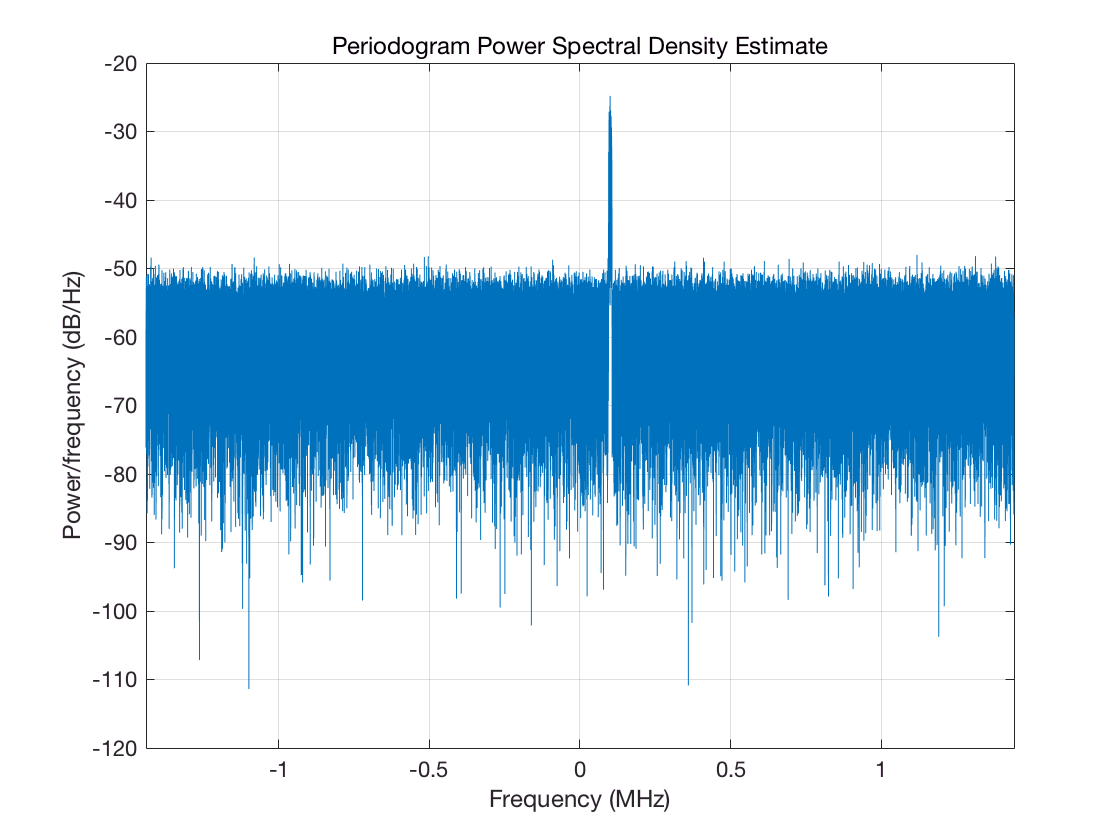

rxSymIF  =   txSymIF;
rxSymIF  =   filter( RlChan, rxSymIF );
rxSymIF  =   awgn( rxSymIF, 0, 'measured' );

hs       =   spectrum.periodogram; figure;psd(hs, rxSymIF, 'Fs',FsIF, 'CenterDC',true);

**5.Receiver**

`5.1 DDC & RRC`

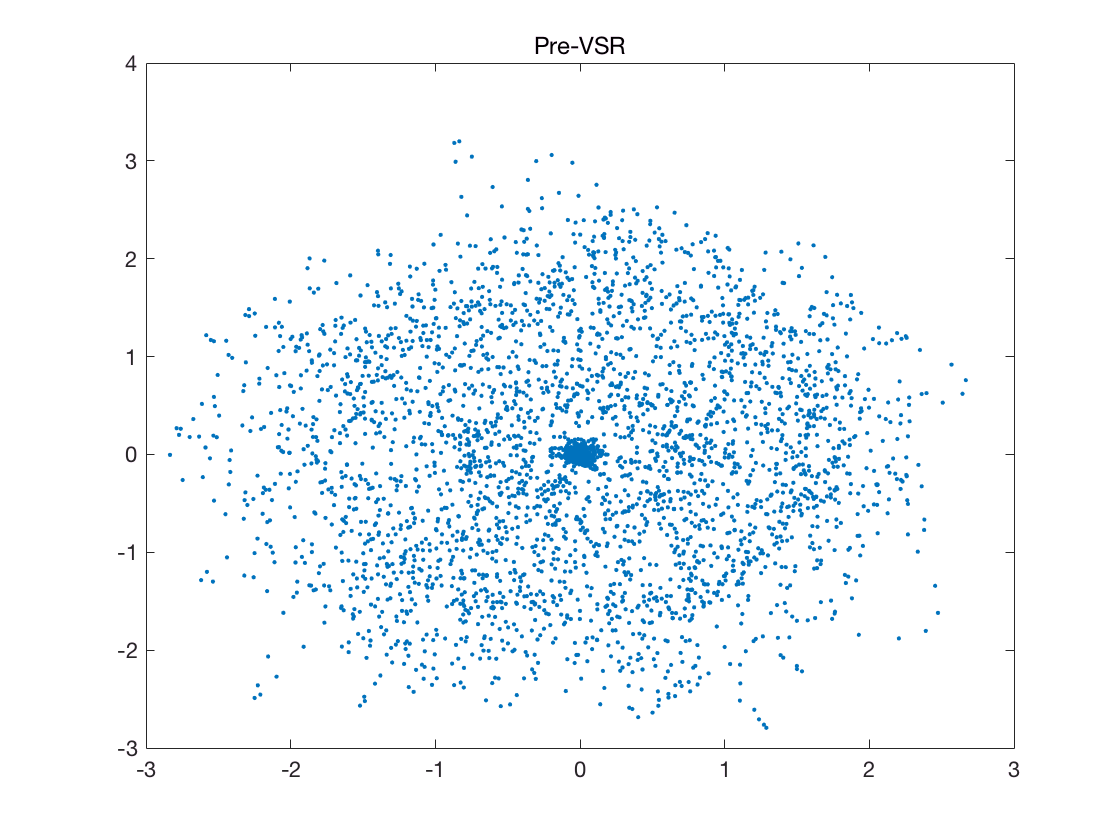

rxSymIF  =   rxSymIF ./ exp( 1j*( 2*pi*rxcFreq*tIF' + rxcPhi0 ) );
rxSymIF  =   FilterConv( rxSymIF.', coefIF' ).' ;
rxSymUp  =   zeros( length(rxSymIF) / IF_OSR, 1 );
rxSymUp  =   rxSymIF( 1 : IF_OSR : end );
rxSymUp  =   FilterConv( rxSymUp.', coefRRC' ).';

figure;  plot(rxSymUp, '.');  title('Pre-VSR');

`5.2 Symbol synchronization & Downsampling`

for ii   =   1:1:BB_OSR
    avePwr(ii) = mean(abs(rxSymUp(ii:BB_OSR:end)));
end
[max T0] =   max(avePwr);

rxSymUp  =   rxSymUp(201:end-200);

rxSym    =   rxSymUp(T0:BB_OSR:end);

fprintf( 'T0 = %d\r\n', T0 );

T0 = 1


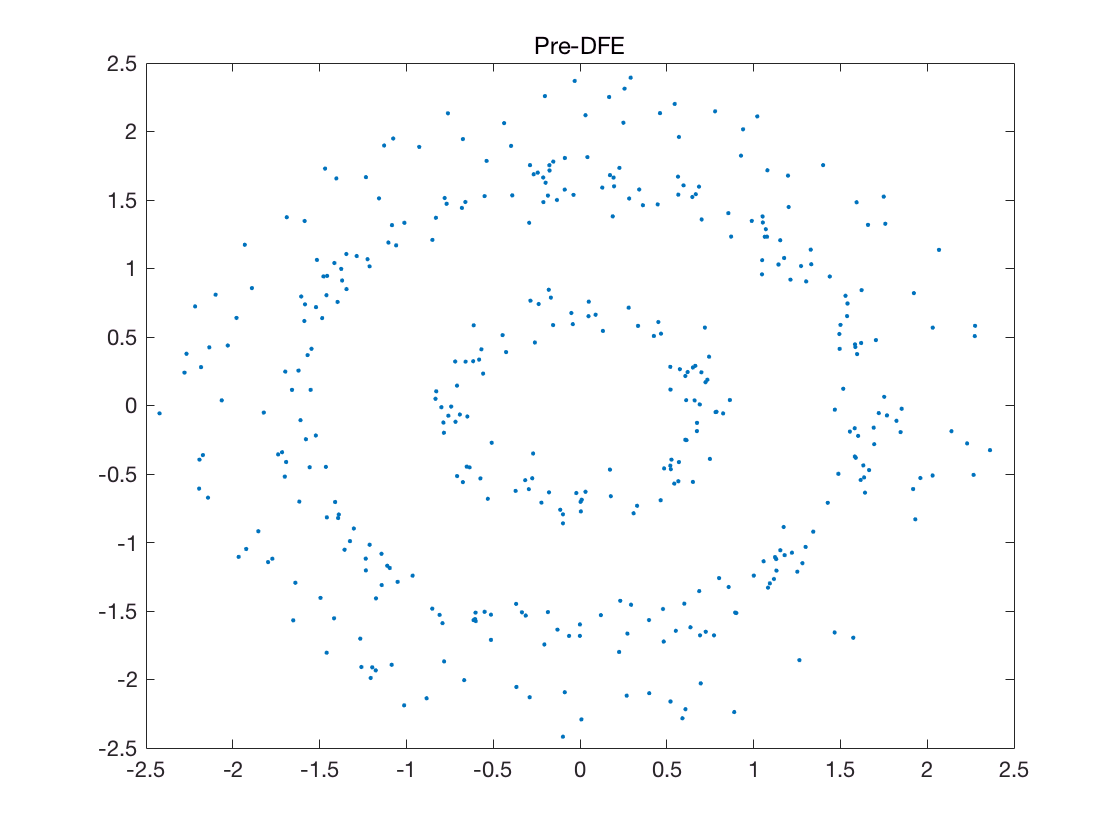


figure;  plot(rxSym,'.');   title('Pre-DFE');

`5.3 ``D``ecision ``F``eedback ``E``qualization (DFE)`

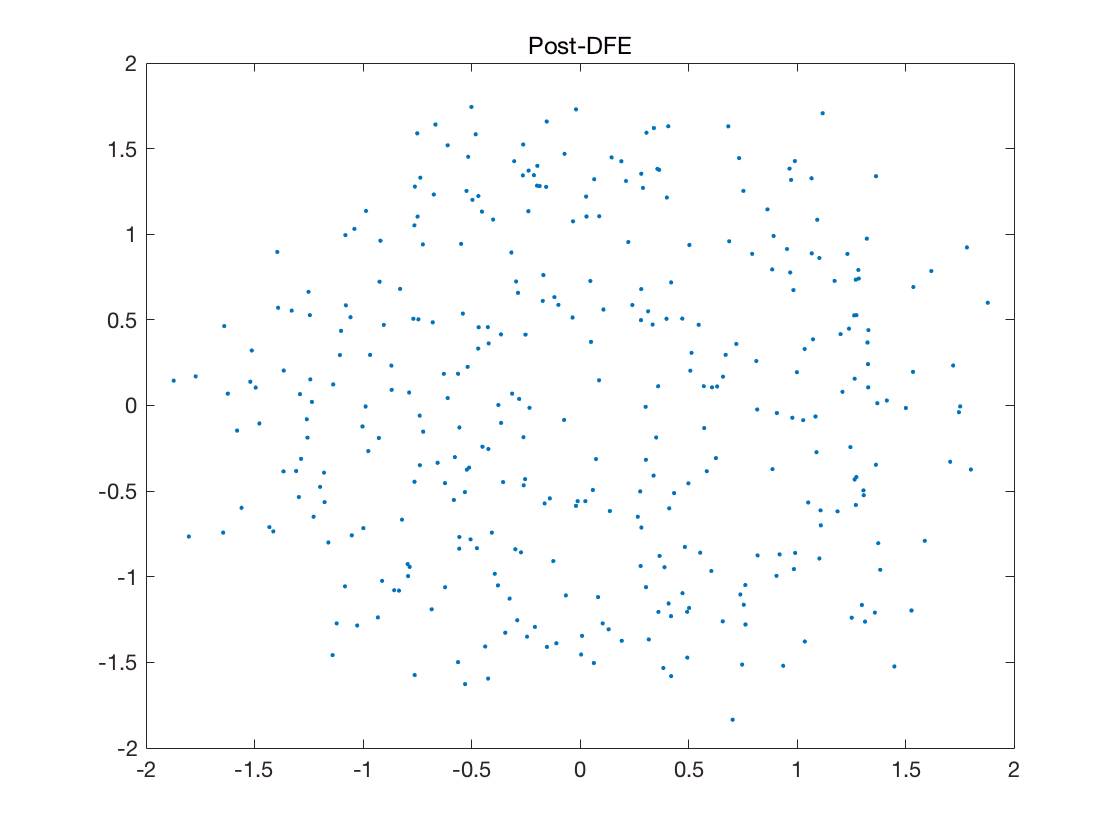

[hMyDFE, rxSymDFE, vyDcs] = fnDFE( hMyDFE, rxSym, [1:nTSHead], txSym );

figure;  plot(rxSymDFE(nTSHead+1:end),'.');  title('Post-DFE');

`5.4 ``P``hase ``L``ocked ``L``oop`` - D``ecision ``F``eedback ``E``qualization (PLL-DFE)`

[hPLLDFE, rxSymPLLDFE, vyDcsPLL] = fnPLLDFE( hPLLDFE, rxSym, [1:nTSHead], txSym );

ii = 16

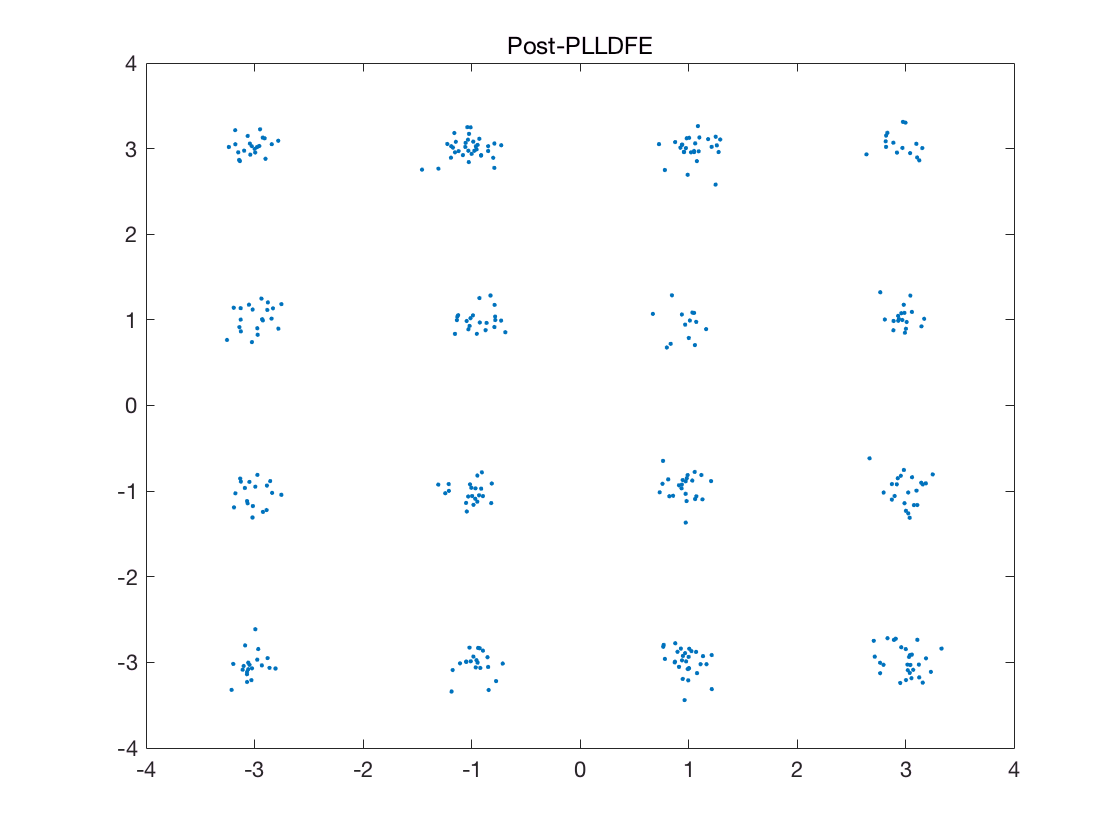


figure;  plot(rxSymPLLDFE(nTSHead+1:end),'.');  title('Post-PLLDFE');

**6.DFE performance**

BitNeq = step(hDem, rxSym);
BERDFE = (sum( vyDcs(nTSHead*log2(M)+1:end)' ~= txBit(nTSHead*log2(M)+1:end) ) / length(txBit(nTSHead*log2(M)+1:end))) * 100;
BERORG = (sum( BitNeq(nTSHead*log2(M)+1:end) ~= txBit(nTSHead*log2(M)+1:end) ) / length(txBit(nTSHead*log2(M)+1:end))) * 100;
BERPLLDFE = (sum( vyDcsPLL(nTSHead*log2(M)+1:end)' ~= txBit(nTSHead*log2(M)+1:end) ) / length(txBit(nTSHead*log2(M)+1:end))) * 100;
fprintf( 'BER : \r\nWithout DFE : %f%%\r\nWith DFE    : %f%%\r\nWith PLLDFE : %f%%\r\n', BERORG, BERDFE, BERPLLDFE );

BER : 
Without DFE : 46.214286%
With DFE    : 51.214286%
With PLLDFE : 0.000000%



EVMDFE = hEVM(rxSymDFE(nTSHead+1:end));
EVMPLLDFE = hEVM(rxSymPLLDFE(nTSHead+1:end));
EVMORG = hEVM(rxSym(nTSHead+1:end));
fprintf( 'EVM : \r\nWithout DFE : %f%%\r\nWith DFE    : %f%%\r\nWith PLLDFE : %f%%\r\n', EVMORG, EVMDFE, EVMPLLDFE );

EVM : 
Without DFE : 46.721822%
With DFE    : 53.135914%
With PLLDFE : 6.193016%


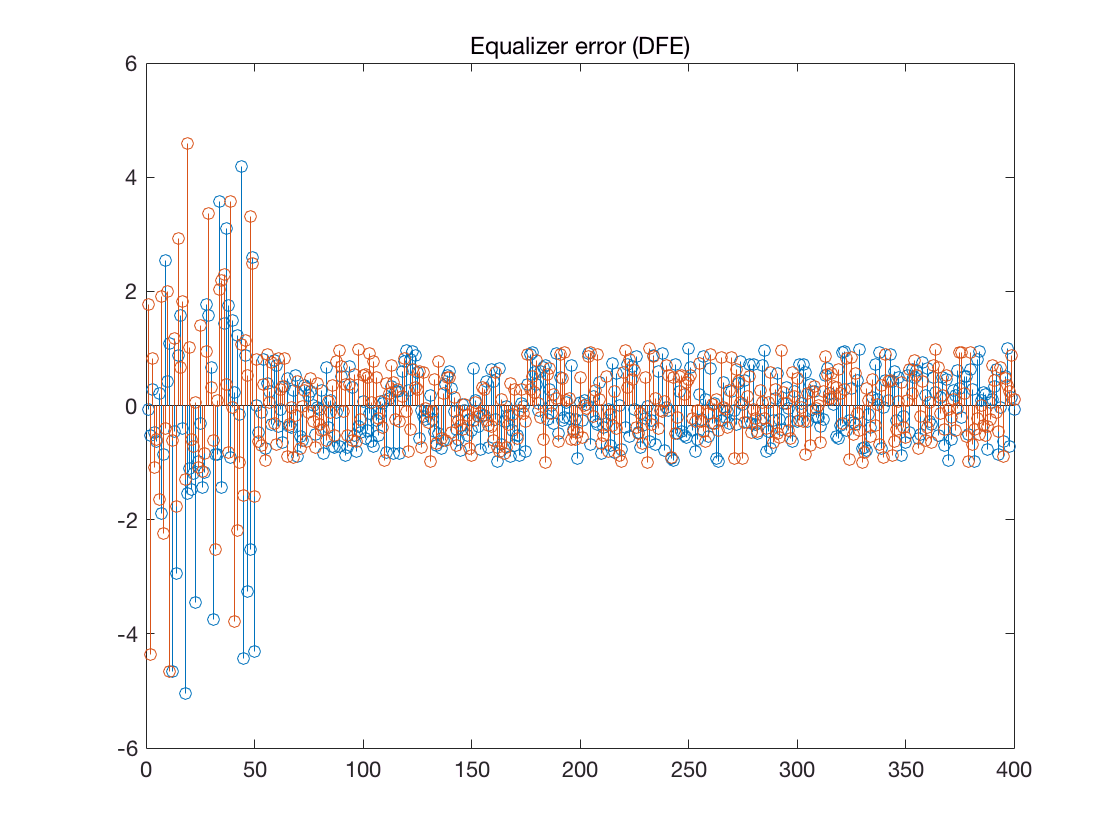


figure;  stem(real(hMyDFE.e));hold on;stem(imag(hMyDFE.e));title('Equalizer error (DFE)');

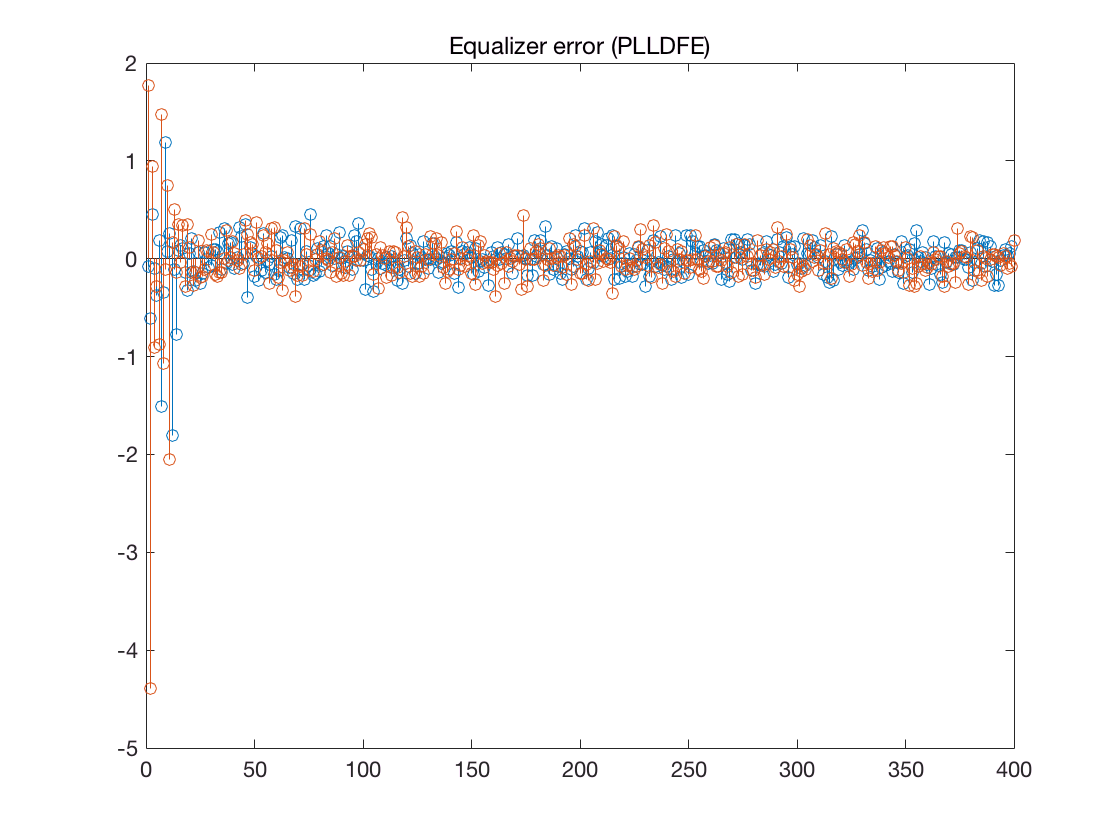

figure;  stem(real(hPLLDFE.e));hold on;stem(imag(hPLLDFE.e));title('Equalizer error (PLLDFE)');

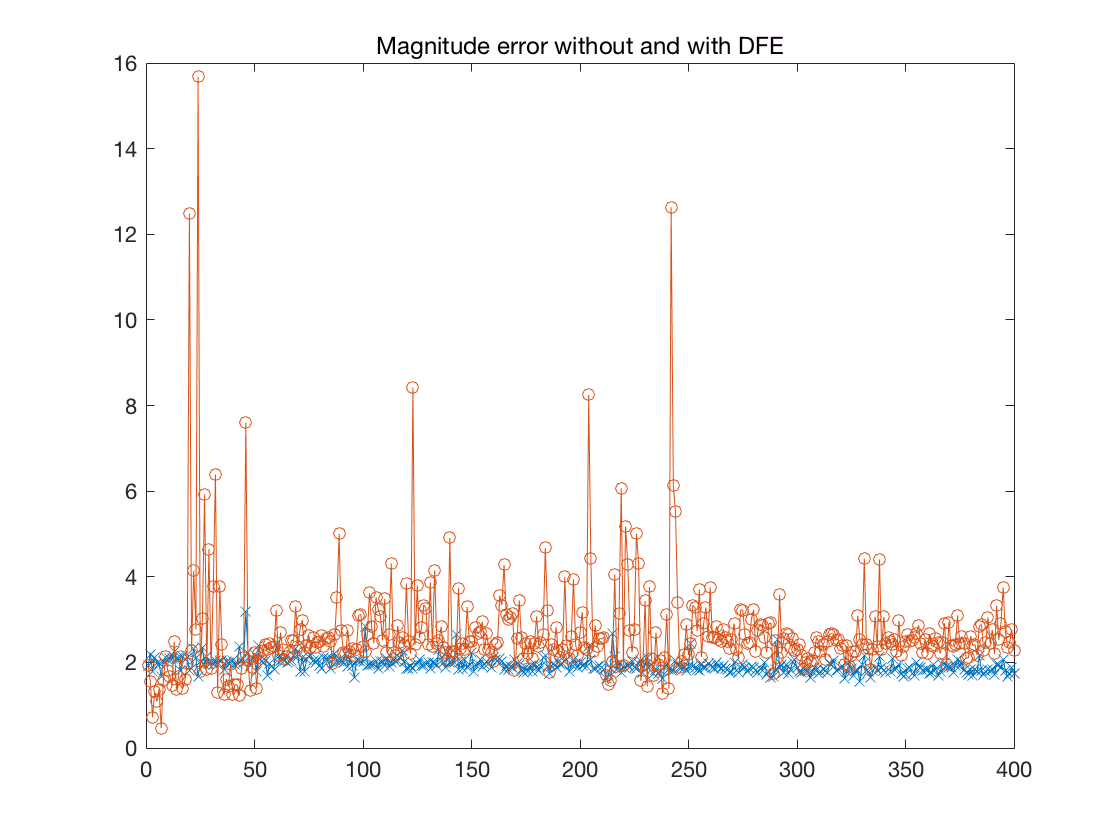


figure;  plot(abs(txSym./rxSym),'x-');hold on;plot(abs(txSym./rxSymDFE),'o-');
title('Magnitude error without and with DFE');

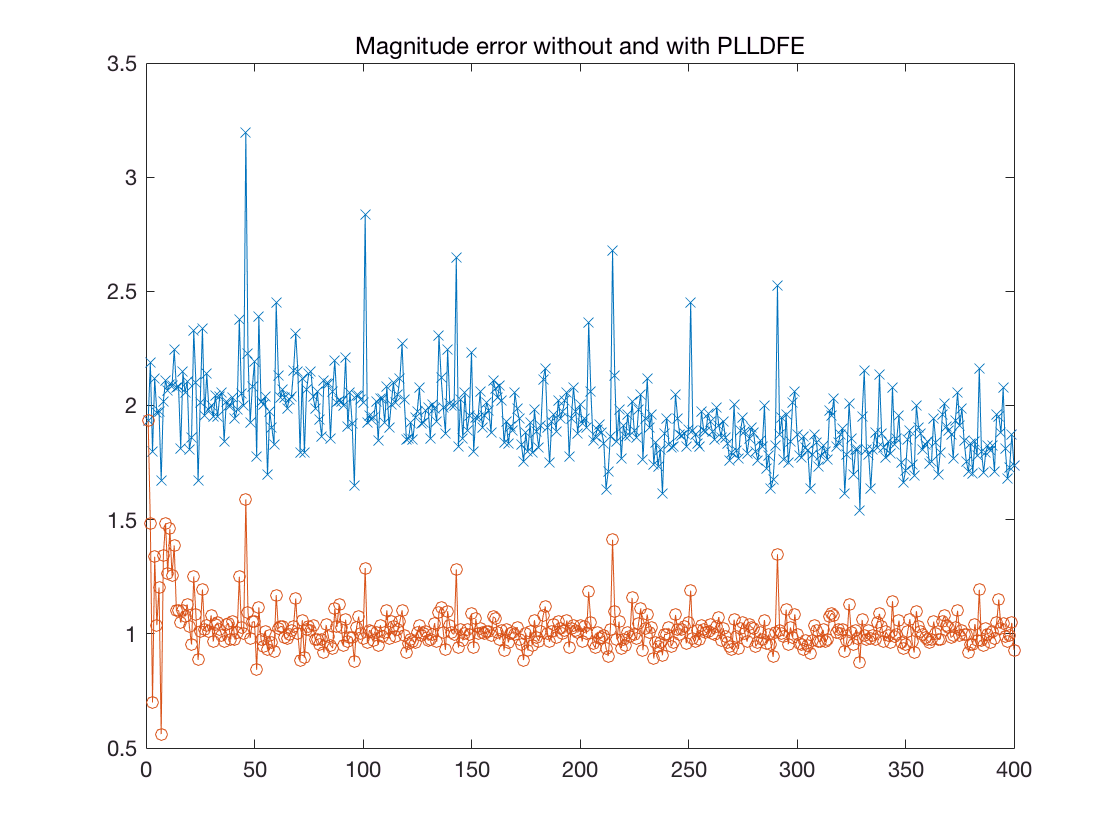


figure;  plot(abs(txSym./rxSym),'x-');hold on;plot(abs(txSym./rxSymPLLDFE),'o-');
title('Magnitude error without and with PLLDFE');

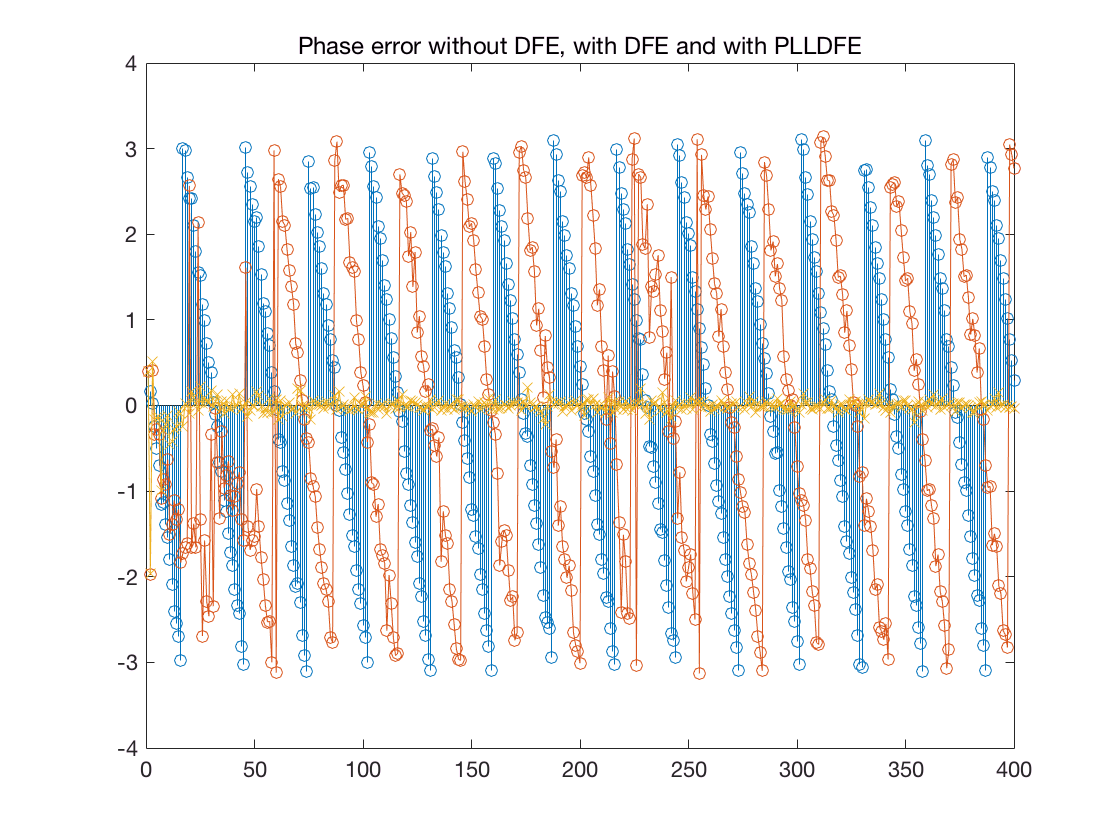


figure;  stem(angle(txSym./rxSym));hold on;plot(angle(txSym./rxSymDFE),'o-');plot(angle(txSym./rxSymPLLDFE),'x-');
title('Phase error without DFE, with DFE and with PLLDFE');

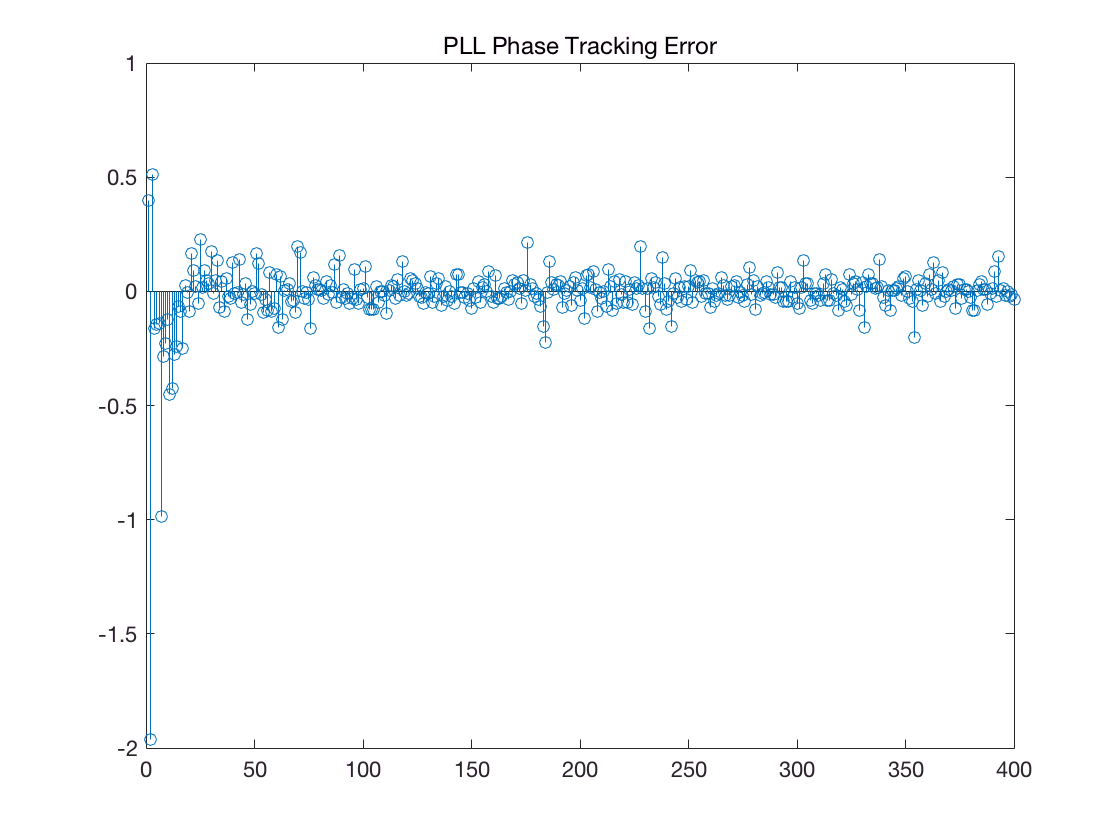

figure;  stem(hPLLDFE.ePhase);
title('PLL Phase Tracking Error');

## Performance of BER

This figure shows the BER performance in different SNR : 

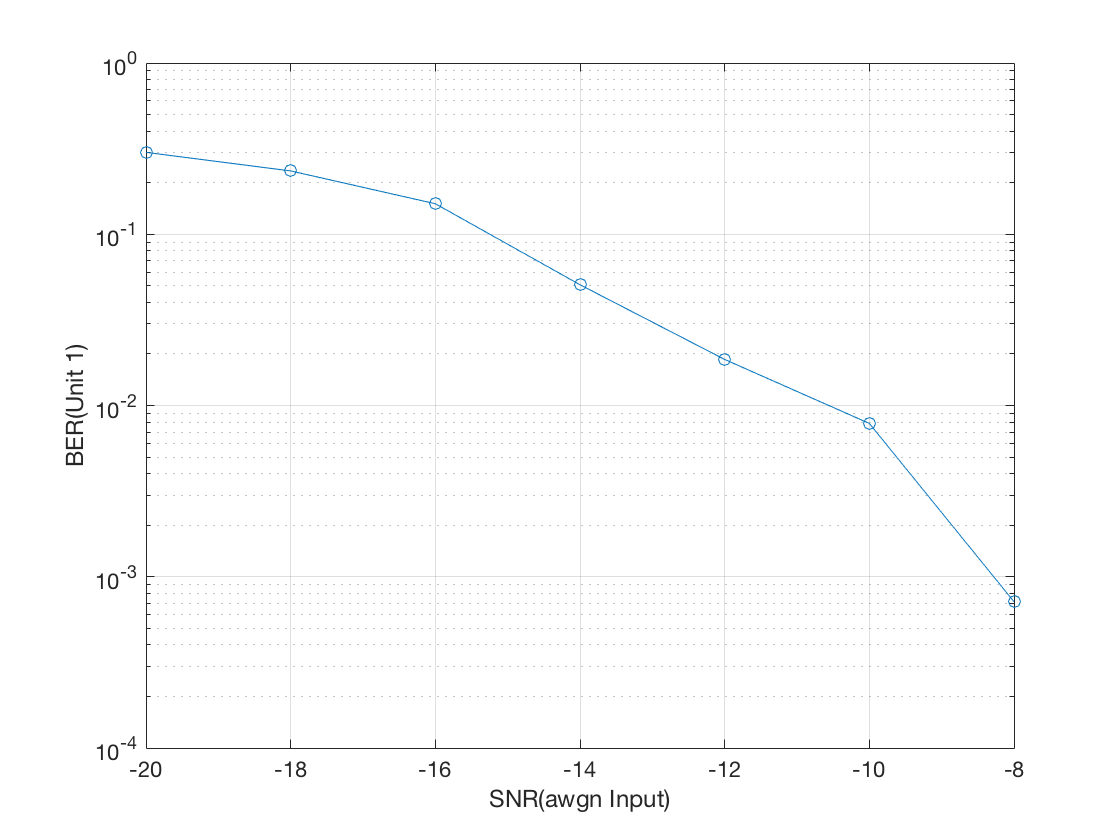

# More about DFE

DFE is a decision feedback  structure, shown below:

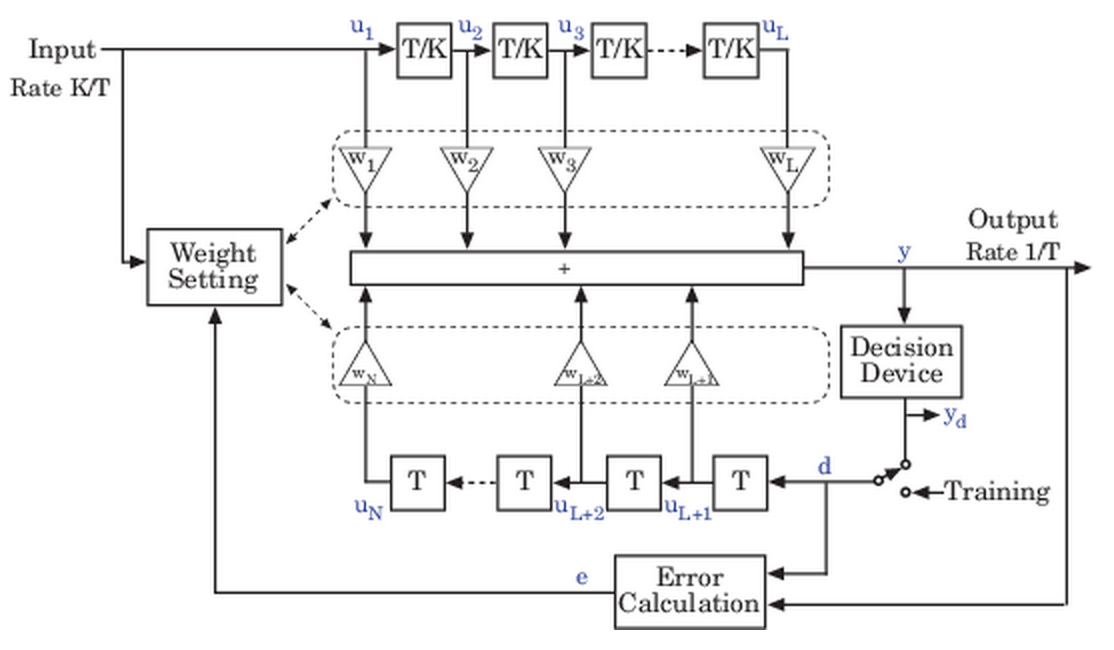

Currently, my code only support symbol-space DFE, so K is always 1.

'Weight setting' part can be LMS, RLS, Kalman and other algorithms. Currently, only RLS is supported.

The core formula of RLS is :


$$K=\text{ }\frac{P\text{ }u}{\lambda +u^H P\text{ }u}$$



$$P=\text{ }\frac{P-K\text{ }u^H P}{\lambda }$$



$$w=w+K^\ast  e$$


K is kalman gain matrix, P is inverse correlation matrix, u is the input vector, e is the error vector, lamda is fogetting factory, H denotes the Hermitian transpose, * denotes the complex conjugate.